# Computes numerically the eigvects and eigvals of the Roskam nonlinear 6-DOF cessna 182

clear; close; clc;

dt = .1; % time step (seconds)
t_total = 20 % total simulation time (seconds)

t_total = 20

angle = 0; % perturbed deflection (degrees)

disablePAH = false; % should disable Adaptive aerocompliance

% for central difference jacobian calucltion
step_size = .01

step_size = 0.0100


k = .2; % comanded value of spring stiffness (N/m)
c_r = .05; % comanded value of rate damping (N*s/rad^2)
%c_c= .005; % commanded value of coulomb damping (N*s/rad^2)
c_c = 0; % commanded value of coulomb damping (N*s/rad^2)
delta_0 = deg2rad(0); % comanded value of deflection (rad)

I_flap = .01; % moment of inertia of flap about hinge line (kg*m^4)

x_0 = [k, c_r, c_c, delta_0, I_flap];

% define IC and controls
time = 1;
t_0 = 1;
t_end = length(time);

throttle = 0;
elevator = 0;
aileron = 0;
rudder = 0;


%k = k + .03*randn(size(time));
%delta_0 = delta_0 + .003*randn(size(time));


% elevator(1.5/dt:2/dt) = ones(size(1.5/dt:2/dt)).*angle.*-pi./180.;
% elevator = elevator  + .003*randn(size(elevator));
VT = 220.1;
Alphaest = 0;
Betaest = 0;
phi = 0;
theta = 0;
psi = 0;
P = 0;
Q = 0;
R = 0;
ned = [0,0,0];
delta_f_1 = 0; % inital flap 1 position
delta_f_dot_1 = 0; % initial flap 1 rate
delta_f_2 = 0; % inital flap 2 position
delta_f_dot_2 = 0; % initial flap 2 rate

cv = [throttle,   elevator,   aileron, rudder, k, c_r, delta_0, c_c];
X_0 = [VT, Alphaest, Betaest, phi, theta, psi, ...
    P, Q, R, ned(1), ned(2), -ned(3), throttle, elevator, ...
    aileron, rudder,...
    delta_f_1, delta_f_dot_1, delta_f_2, delta_f_dot_2]';

y = X_0;


## Now the simulation is set up we can compute the jacobian

num_outputs = 20; % should be the same as length of X_0

X_dot = Roskam_6DOF_C182(time, y, cv, I_flap, disablePAH) % quick test that it can be evaluated

X_dot =    -0.0000
    0.0000
         0
         0
         0
         0
         0
         0
         0
  220.1000




Jac = computeJacobian(@(x) Roskam_6DOF_C182(time, x, cv, I_flap, disablePAH), X_0, num_outputs, step_size, true)

Jac = 1.0e+03 *

   -0.0000    0.0160         0         0   -0.0321         0         0   -0.0002         0         0         0         0         0   -0.0016         0         0   -0.0036         0   -0.0036         0
    0.0073   -0.0021         0         0         0         0         0    0.0010         0         0         0         0         0   -0.0002         0         0   -0.0005         0   -0.0005         0
         0         0   -0.0002    0.0001         0         0   -0.0000         0   -0.0010         0         0         0         0         0         0    0.0001         0         0         0         0
         0         0         0         0         0         0    0.0010         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    0.0010         0         0         0         0         0         0         0         0         0         


% remove the functions of state we are not intrested in
% remove postion XYZ (10-12) and control surfaces (13-16)
position_vars = [10:12]

position_vars =     10    11    12


control_surf_vars = [13:16]

control_surf_vars =     13    14    15    16


% Jac(10:16, :) = []
% Jac(:,10:16) = []
vars_to_remove = [position_vars, control_surf_vars]

vars_to_remove =     10    11    12    13    14    15    16



% filter to only longitudinal modes only - (remove position and control first)
lat_dir_vars = [3,4,6,7,9]

lat_dir_vars =      3     4     6     7     9


% we will only need one flap for longitudinal because they are symmetric
second_flap_vars = [19,20]

second_flap_vars =     19    20


vars_to_remove = [vars_to_remove, lat_dir_vars, second_flap_vars]

vars_to_remove =     10    11    12    13    14    15    16     3     4     6     7     9    19    20



% remove the vars we are unitrested int
Jac(vars_to_remove, :) = []

Jac =    -0.0356   15.9904         0         0  -32.1469         0         0   -0.1590         0         0         0         0         0   -1.5753         0         0   -3.6352         0   -3.6352         0
    7.3021   -2.1158         0         0         0         0         0    0.9793         0         0         0         0         0   -0.2046         0         0   -0.4721         0   -0.4721         0
         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0  -19.2620         0         0         0         0         0   -4.3372         0         0         0         0         0  -35.2560         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000         0

Jac(:, vars_to_remove) = []

Jac =    -0.0356   15.9904  -32.1469   -0.1590   -3.6352         0
    7.3021   -2.1158         0    0.9793   -0.4721         0
         0         0         0    1.0000         0         0
         0  -19.2620         0   -4.3372         0         0
         0         0         0         0         0    1.0000
    0.0000 -181.0643         0         0 -925.4512  -50.0000



[W, Lambda] = eig(Jac);

lambda = diag(Lambda);

% Sort in descendong order of real components of eigen values
% Sort the real parts in descending order and get the sorting indices
[~, sortIndices] = sort(real(lambda), 'descend');

% Reorder the eigenvalues and eigenvectors accordingly
lambdaSorted = lambda(sortIndices)

lambdaSorted =   10.6628 + 0.0000i
  -2.2867 + 5.3009i
  -2.2867 - 5.3009i
 -12.7766 + 0.0000i
 -24.9007 +17.3651i
 -24.9007 -17.3651i


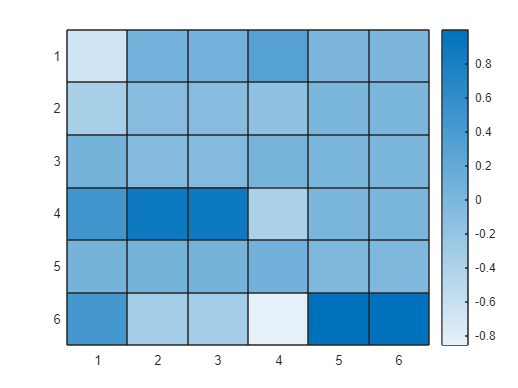

WSorted = W(:, sortIndices);


heatmap(real(WSorted))

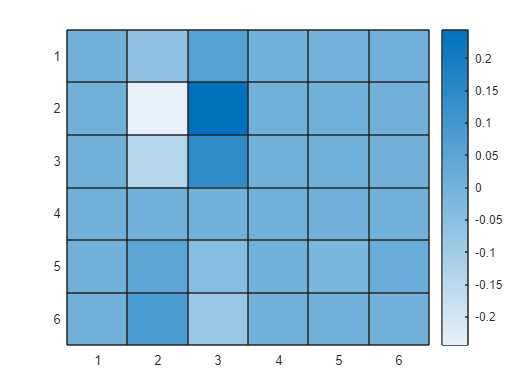

heatmap(imag(WSorted))

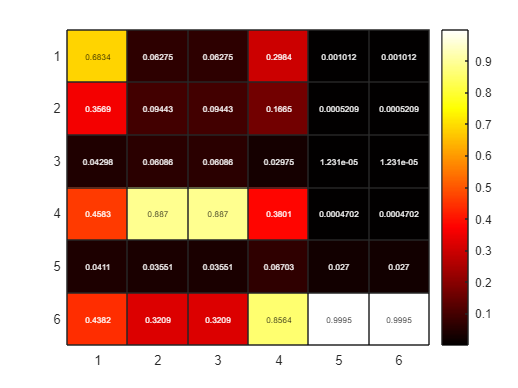


heatmap(abs(real(WSorted))); colormap("hot")

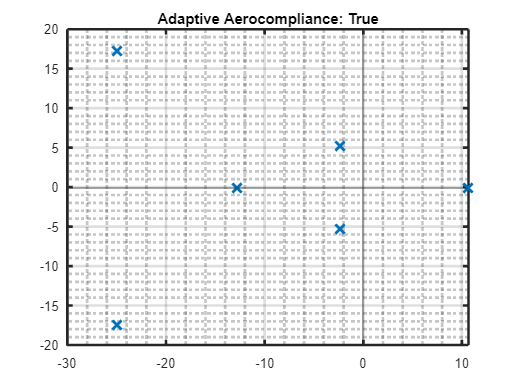


plot(lambdaSorted,"x", "MarkerSize",10, "LineWidth",2)
grid minor;
grid on;
logical_strings = ["False", "True"]; % create strrings to display true or flase 
title(sprintf("Adaptive Aerocompliance: %s", logical_strings(~disablePAH + 1) )) % add title
xline(0,"Alpha",.5); yline(0,"Alpha",.5)
set(gca, "LineWidth",2)

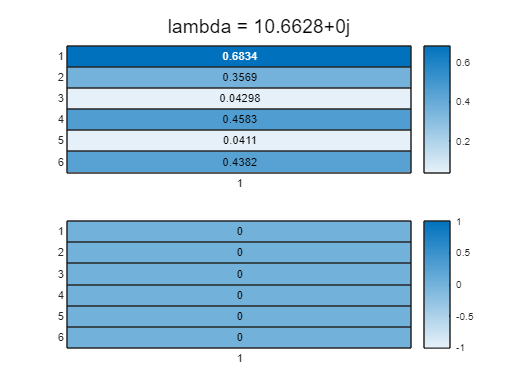

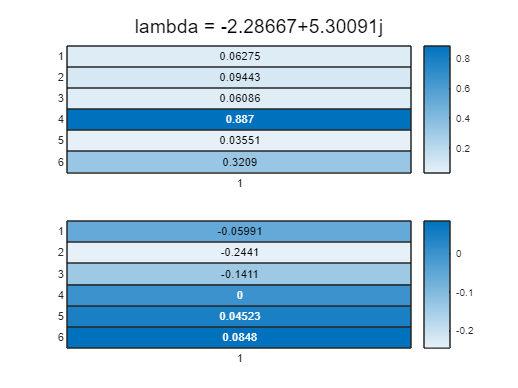

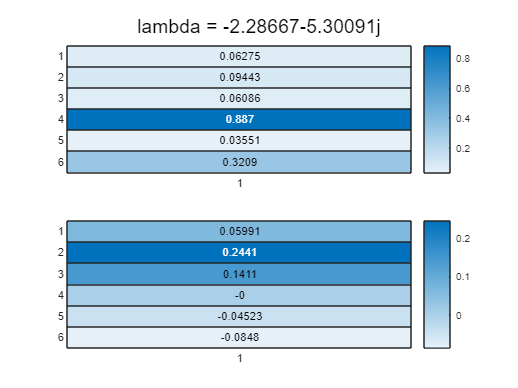

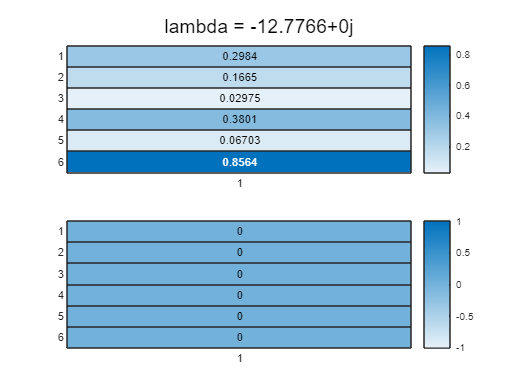

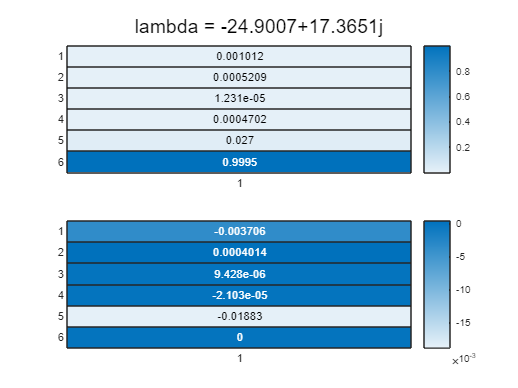

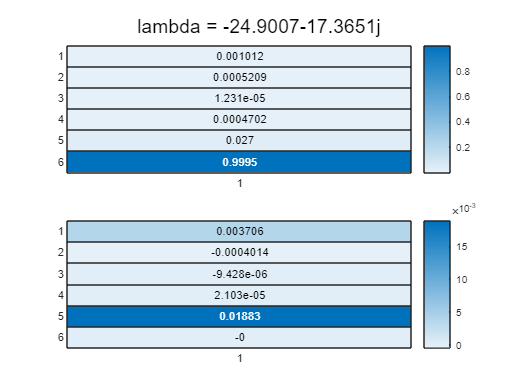


for column = 1:size(WSorted,2)
    figure;
    sgtitle(sprintf("lambda = %g%+gj", real(lambdaSorted(column)), imag(lambdaSorted(column))))
    subplot(2,1,1)
    % heatmap(real(WSorted(:,column)))
    heatmap(abs(real(WSorted(:,column)))) % tryin abs to help see whats involed in the mode
    subplot(2,1,2)
    heatmap(imag(WSorted(:,column)))
end